## Tutorial 4: Eigenvalues and diagonalization

In this Tutorial you will learn how to compute eigenvalues and eigenvectors in Matlab and how to diagonalize a symmetric matrix.

### Computing eigenvalues and eigenvectors

You can use eig to compute the eigenvalues and eigenvectors of a matrix. Use help to find out about the eig command.

help eig

Now you are ready to use the command with a matrix **A**

A = [2 -1  0
    -1  2 -1
    0  -1  2];
[V, L]=eig(A);

The 3x3 matrix **V** contains the three eigenvectors of **A** as its columns. The diagonal 3x3 matrix **L** contains the three eigenvalues of **A** on its diagonal. 

Recall that eigenvalues and eigenvectors satisfy:


$${\bf{Av}}=\lambda {\bf{v}}$$


You can check these relations by computing ${\bf{Av}}-\lambda {\bf{v}}$, which should be zero:

A*V(:,1)-L(1,1)*V(:,1)

Here, V(:,1) is the first eigenvector of **A** (first column of **V**), L(1,1) is the first eigenvalue of A (first diagonal element of **L**). Note that we see again the familiar numerical error, i.e., ${\bf{Av}}-\lambda {\bf{v}}$ is not exactly zero, but very nearly zero.

 You can check that all three eigenvalues/eigenvectors satisfy this relation:

A*V(:,1)-L(1,1)*V(:,1)
A*V(:,2)-L(2,2)*V(:,2)
A*V(:,3)-L(3,3)*V(:,3)

You can also write all three relations in matrix form:


$${\bf{AV}}= {\bf{VL}}$$


Check this numerically:

A*V-V*L

### Diagonalization

To transpose a matrix, use the '. For example, to get the transpose of A, simply write:

A'

If you multiply **V** and its transpose, you get the identity matrix:

V'*V
V*V'

Note that, suprisingly, here ${\bf{V}}^T{\bf{V}}= {\bf{V}}{\bf{V}}^T$. Thus, the inverse of **V** is its transpose, ${\bf{V}}^{-1}={\bf{V}}^T$. Multiplying ${\bf{AV}}= {\bf{VL}}$ from the left by ${\bf{V}}^T$ thus gives


$${\bf{V}}^T{\bf{AV}}= {\bf{L}}$$


Note that A is not diagonal, but after multiplying from the left and right by ${\bf{V}}^T$ and **V**, we obtain the diagonal matrix **L**. In this sense, the matrix **V**, diagonalizes the matrix **A**.

You can diagonalize in Matlab as follows:

V'*A*V

### Normalization of eigenvectors

Recall from class that eigenvectors are only known up to an arbitrary multiplicative constant. That is, if **v** is an eigenvector, the $\alpha \bf{v}$ is also an eigenvector for any non-zero scalar $\alpha$. You can thus create other eigenvectors of **A**:

b1 = 5*V(:,1);
b2 = -0.2*V(:,2);
b3 = 10*V(:,3);
B = [b1 b2 b3]; % the 3x3 matrix B has the three vectors b1, b2 and b3 as its columns

You can check that b1, b2 and b3 are indeed eigenvectors of **A**:

A*b1-L(1,1)*b1
A*b2-L(2,2)*b2
A*b3-L(3,3)*b3

Or in matrix form:

A*B-B*L

The inverse of **B**, however, is no longer its transpose:

B'*B
B*B'

But since ${\bf{B}}^T{\bf{B}}$ is still a diagonal matrix, **B** also diagonalizes **A**: 

B'*A*B

But note that ${\bf{B}}^T{\bf{AB}}$ is no longer equal to **L**. It is equal to ${\bf{B}}^T{\bf{BL}}$

B'*B*L

Since eigenvectors are only defined up to a multiplicative constant, it is common practice to "normalize" them so that ${\bf{v}}^T{\bf{v}}=1$. This is what Matlab's eig command automatically does. 

You can get the eigenvectors $\bf{v}$ that you computed using Matlab's back from the eigenvectors b1, b2, b3 by normalizing the eigenvectors such that ${\bf{b}}^T{\bf{b}}=1$. You can achieve this by dividing $\bf{b}$ by $\sqrt{{\bf{b}}^T{\bf{b}}}$:

b1 = b1/sqrt(b1'*b1);
b1'*b1

b2 = b2/sqrt(b2'*b2);
b2'*b2

b3 = b3/sqrt(b3'*b3);
b3'*b3

After this last step, the eigenvectors b1, b2, b3 are exactly the same as the eigenvectors contained in the matrix $\bf{V}$. There is, however, one more issue: the sign of and eigenvector is still not uniquely defined, even when one enforces that ${\bf{v}}^T{\bf{v}}=1$. Define an eigenvector ${\bf{u}} = -{\bf{v}}$ .

u=-V(:,1);

Then ${\bf{u}}^T{\bf{u}}=1$ and ${\bf{v}}^T{\bf{v}}=1$, but the vectors are clearly not the same.

u'*u
V(:,1)'*V(:,1)
u-V(:,1)

Nonetheless, none of these non-uniqueness issues are critical to diagonalization. Do you know why?

### Exercises

1. Why is ${\bf{B}}^T{\bf{BL}}$ (see above for definitions) a diagonal matrix?

**Solution.**

The matrix ${\bf{B}}^T{\bf{B}}$ is diaginal by its construction and so is the matrix **L**. Since the product of two diagonal matrices is also diagonal, ${\bf{B}}^T{\bf{BL}}$ is diagonal.

2 The determinant of a matrix **A** is equal to the product of the eigenvalues. Write a code that uses only the eig command and basic operations (such as multiplication and addition) to compute the determinant of the matrix

A= [ 2 -1  0
    -1  2 -1
     0 -1  2];

You can check your answer by using Matlab's det command. As usual, find out how to use the det command by using the help command.

**Solution**

Compute the eigenvalues of A.

 [U,L]=eig(A);

The eigenvalues are the diagonal elements of L. We can thus compute det(A) by taking the product of the diagonal elements of A:

 detA = L(1,1)*L(2,2)*L(3,3)

We use Matlab's det command to check our result

 det(A)

3. Compute the eigenvalues of the 1000x1000 matrix

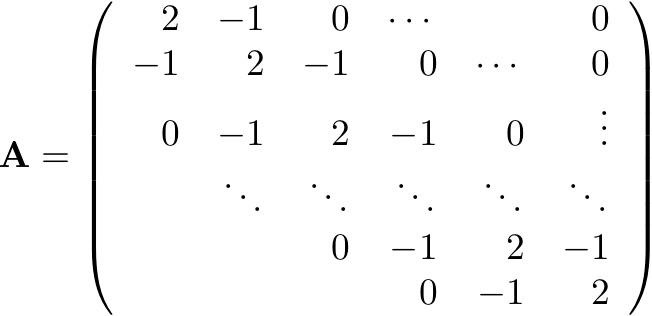

You can use this code to create **A**

 clear % clear old variables
 n = 100;
 A = 2*eye(n,n)-diag(ones(n-1,1),1)-diag(ones(n-1,1),-1);

You can visualize such a large matrix by plotting the values of the elements as colors:

 figure
 imagesc(A)

***Solution***

Use the eig command to compute the eigenvalues and eigenvectors of **A**. 

 [U,L]=eig(A);

Make a plot of the eigenvalues by plotting the diagonal elements of the matrix **L** that you obtain fromt the eig command and that contains the eigenvalues of **A** on the diagonal. You can do this by using this command:

figure
plot(diag(L))

Diagonalize the matrix **A**. Make a plot of the diagonalized **A**. 

Ad = U'*A*U;
figure
imagesc(Ad)